tic

if ~exist("colorset")
    load colorset.mat
end
% Step 1: Set order of the stacking area plot
% Usually show baseloads first, the peakings are on top
% Set a type's order to 0 to remove it from the figure

yr = 2022; mon = 12;
RegionID = 'QLD1';
% Remember to change the RegionID
filepath = fileparts(pwd);
load(filepath + sprintf("\\NEMdata\\%s\\CombinedTable%4d%02d",RegionID,yr,mon));

% new variable names for data from CombinedTable
gen = array2table(CombinedTable.MW,"VariableNames",colorset.types(1:10));
loads = array2table(CombinedTable.MWdpload,"VariableNames",colorset.types(12:13));
loads.export = CombinedTable.MWexport;

% colorset is sorted by your order setting. 
% If a type's order is zero, it will be removed (won't be shown on the figure)
stackorder = sortrows(colorset,"order");
stackorder = stackorder(stackorder.order ~= 0,:);

% Sort the gen, demand data according to the order that you have set.
gen = gen(:,stackorder.types(ismember(stackorder.types,gen.Properties.VariableNames)));
loads = loads(:,stackorder.types(ismember(stackorder.types,loads.Properties.VariableNames)));

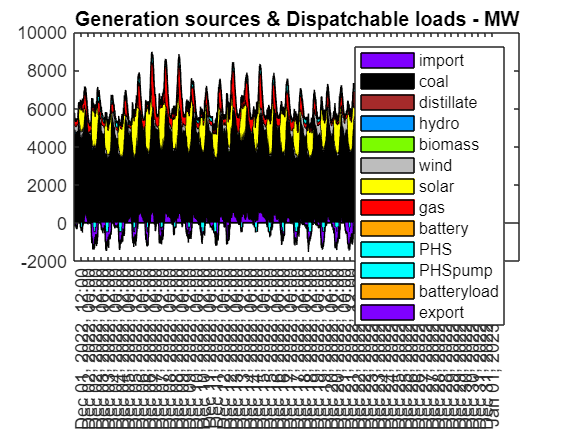

% plot
clf
area(CombinedTable.SETTLEMENTDATE,gen.Variables)
hold on
area(CombinedTable.SETTLEMENTDATE,-loads.Variables)
colororder(stackorder.color)
legend(stackorder.types)
xticks(CombinedTable.SETTLEMENTDATE(144:144:height(gen)))
title('Generation sources & Dispatchable loads - MW')

toc

Elapsed time is 1.778483 seconds.


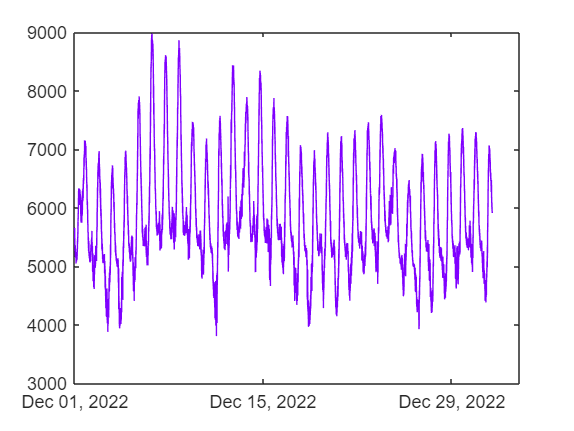

clf
plot(CombinedTable.SETTLEMENTDATE,sum(gen.Variables,2)-sum(loads.Variables,2))

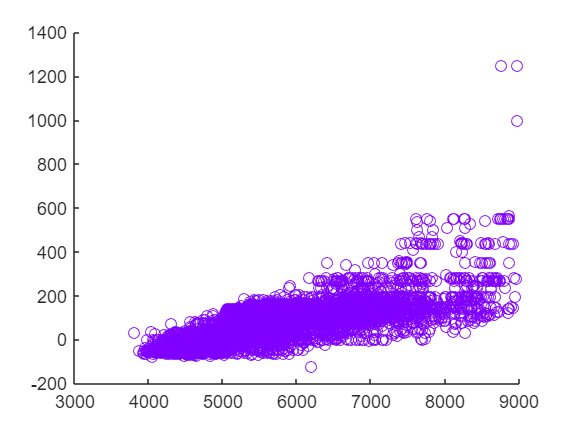

clf
scatter(sum(gen.Variables,2)-sum(loads.Variables,2),CombinedTable.RRP)